# Mid-Term project: Tumor Segmentation through Fuzzy Inference with genetic weight tuning

## Initialization

### Settings

windowSizes=struct("mean",4,"kurt",4); %sizes of sliding windows
floodingSettings=struct("borderThresh",0.25,"wallDistanceThresh", 2, "recognizeSeed",1.3); %settings for flooding:
% - borderThresh: threshold above which a normalized gradient is considered a
%border
% - wallDistanceThresh: distance from a wall that will stop the flooding
% - to be able to find an acceptable seed the max intensity must be at
% least {recognize seed} times the median intensity

### Data files identification

 
% Download
imageDir = fullfile(pwd, "BraTS","sampleBraTSTestSetValid", "imagesTest");
labelDir = fullfile(pwd, "BraTS","sampleBraTSTestSetValid", "labelsTest");
imageFiles = dir(fullfile(imageDir, "*.mat"));
labelFiles = dir(fullfile(labelDir, "*.mat"));

% Extract file names
imageSubjects = string(erase({imageFiles.name},".mat"));
labelSubjects = string(erase({labelFiles.name},".mat"));

% Visualize available files
fprintf("Soggetti con immagini disponibili: %s\nSoggetti con etichette disponibili: %s", strjoin(imageSubjects, ", "), strjoin(labelSubjects, ", "))

Soggetti con immagini disponibili: BraTS446, BraTS447, BraTS455, BraTS461, BraTS463
Soggetti con etichette disponibili: BraTS446, BraTS447, BraTS455, BraTS461, BraTS463

clear imageFiles labelFiles

### Run this section to execute the script on **random** slices

slicesNumber=10;
rng(0,'twister');

 

slices=strings(slicesNumber,2);

for i=1:slicesNumber
    slices(:,1)=imageSubjects(randi([1,length(imageSubjects)], slicesNumber, 1));
    slices(:,2)=randi([40,112],slicesNumber, 1);
end

### Run this section to execute the script on **specific** slices

How to specify the selected slices: modify the *nxd* matrix `slices `specifying for each line file and slice number (do not include the `.mat` extension)

% format: [file, sliceNumber; file, sliceNumber]
% sliceNumber is an integer in [1,152]
slices=["BraTS446", 52; "BraTS447", 72];

 

slicesNumber=size(slices,1);

## Data Loading

images=[];

for i=1:slicesNumber
    % Data loading (could be optimized since it loads the same file so many times)
    dataFileName = fullfile(imageDir,slices(i,1));
    labelFileName = fullfile(labelDir,slices(i,1));
    data = load(dataFileName);
    label = load(labelFileName);
    data = data.cropVol(:,:,str2double(slices(i,2)),1);
    label = label.cropLabel(:,:,str2double(slices(i,2)));

    image=MRImage(data);
    image.label=label;

    %object creation and assignment to matrix
    images=[images,image];
end

imagesL=length(images);

%cleanup
clear data dataFileName i image imageDir imageSubjects label labelDir labelFileName labelSubjects slicesNumber

### Visualize data and labels

selection=0; %slide to select slice
if selection~=0
    figure
    subplot(1,2,1)
    imshow(images(selection).image)
    subplot(1,2,2)
    imshow(images(selection).label)
end

## Compute various information on the image

%computations:
for i=1:imagesL
    images(i).preprocessing(windowSizes); %computes all values displayed underneath
end


%visualization of computed data
selection=0;
if selection~=0
    figure
    subplot(2,3,1)
    imshow(images(selection).image)
    title("original")
    subplot(2,3,2)
    imshow(images(selection).slidingMean)
    title("Mean in sliding window")
    subplot(2,3,3)
    imagesc(images(selection).gradientMods)
    title("Gradient")
    axis equal
    subplot(2,3,4)
    stats=sprintf("median:%.3f\nmax:%.3f\nmin:%.3f", images(selection).medianValue, images(selection).max, images(selection).min);
    text(0.1,0.6,stats)
    axis off
    subplot(2,3,5)
    imagesc(images(selection).slidingKurt)
    title("Kurtosis in sliding window")
    axis equal
    subplot(2,3,6)
    imagesc(images(selection).distanceFMedian)
    title("Distance from median")
    axis equal
end
clear stats

## Seeding and flooding to identify a cancerous area based on brightest point seed and gradient walls

%computations:
coordinates=zeros(imagesL,2);
for i=1:imagesL
    coordinates(i,:)=images(i).seedAndFlood(floodingSettings);
end

% visualization

selection=0;
if selection~=0
    figure
    subplot(1,2,1)
    seedimage=cat(3, images(selection).image, images(selection).image, images(selection).image);
    seedimage(coordinates(selection,1), coordinates(selection,2), :)=[1,0,0];
    imshow(seedimage)
    title("seed location")
    subplot(1,2,2)
    if isempty(images(selection).floodedMap)
        axis off
        text(0.1,0.5, "flooding was inconclusive")
    else
        imagesc(images(selection).floodedMap-((images(selection).image==0)),[-1 20])
        title("flooded area")
        axis equal
    end
end

## Application to the FIS and genetic alorithm to select the best weights

fis=readfis("SugenoImageRecognition.fis");

### Evaluating images before weight tuning

results=cell(imagesL, 1);
for i=1:imagesL
    if isempty(images(i).floodedMap)
        flood=ones(images(i).d)*-1;
    else
        flood=images(i).floodedMap;
    end
    input=[images(i).slidingMean(:),images(i).gradientMods(:),flood(:),images(i).slidingKurt(:),images(i).distanceFMedian(:)];
    result=reshape(evalfis(fis, input), images(i).d);
    results{i}=result; %should be split to binary at 0.5, but not done for visualization purposes 
end


% visualization

selection=0;
if selection~=0
    figure
    subplot(1,2,1)
    imshow(images(selection).label)
    title("label")
    subplot(1,2,2)
    imshow(results{selection})
    title("inference")
end

### Tuning

[bestWeights, bestThresh, genNumber]=geneticAlgorithm(fis, images, 10, 300, 3, 0.9); %it takes a while

Generation:1

Evaluation of genome:1
Evaluation of genome:2
Evaluation of genome:3
Evaluation of genome:4
Evaluation of genome:5
Evaluation of genome:6
Evaluation of genome:7
Evaluation of genome:8
Evaluation of genome:9
Evaluation of genome:10
improvement wrt last generation:Inf less errors

Generation:2

Evaluation of genome:1
Evaluation of genome:2
Evaluation of genome:3
Evaluation of genome:4
Evaluation of genome:5
Evaluation of genome:6
Evaluation of genome:7
Evaluation of genome:8
Evaluation of genome:9
Evaluation of genome:10
Evaluation of genome:11
Evaluation of genome:12
Evaluation of genome:13
Evaluation of genome:14
Evaluation of genome:15
Evaluation of genome:16
Evaluation of genome:17
improvement wrt last generation:790190 less errors

Generation:3

Evaluation of genome:1
Evaluation of genome:2
Evaluation of genome:3
Evaluation of genome:4
Evaluation of genome:5
Evaluation of genome:6
Evaluation of genome:7
Evaluation of genome:8
Evaluation of genome:9
Evaluation of genome

fprintf("best weights:%f\nbest thershold:%f",[bestWeights], bestThresh)

best weights:0.391674
best thershold:0.639588best weights:0.781547
best thershold:0.003636best weights:0.501339
best thershold:0.396500best weights:0.831869
best thershold:

### Final FIS

%replacing weights
for i=1:length(bestWeights)
    fis.rules(i).Weight=bestWeights(i);
end

%computing inferences
resultsf=cell(imagesL, 1);
for i=1:imagesL
    if isempty(images(i).floodedMap)
        flood=ones(images(i).d)*-1;
    else
        flood=images(i).floodedMap;
    end
    input=[images(i).slidingMean(:),images(i).gradientMods(:),flood(:),images(i).slidingKurt(:),images(i).distanceFMedian(:)];
    result=reshape(evalfis(fis, input), images(i).d);
    resultsf{i}=result>bestThresh;
end

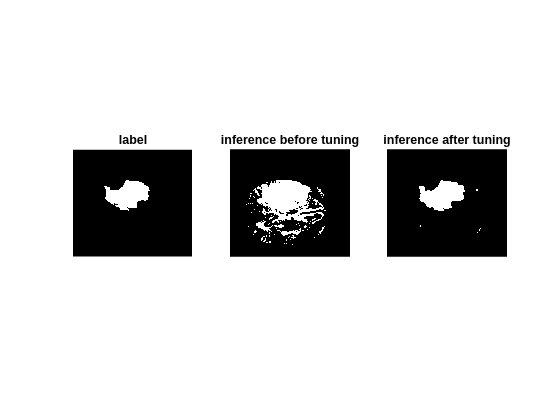


% visualization

selection=3;
if selection~=0
    figure
    subplot(1,3,1)
    imshow(images(selection).label)
    title("label")
    subplot(1,3,2)
    imshow(results{selection}>0.5)
    title("inference before tuning")
    subplot(1,3,3)
    imshow(resultsf{selection})
    title("inference after tuning")
end